# Linear Segment with Parabolic Blend (LSPB)

- suitable joint space trajectories

- has a trapezoidal velocity profile

- appropriate when a constant velocity is desired along a portion of the path

- It consists of 3 parts:

- $t_0 \to t_b :$ Quadratic polynomial and this results in a linear ramp velocity.

- At $t_b$: At the **blend time, **switch to linear function and this corresponds to constant velocity.

- $t_b \to t_f :$ The trajectory switch to quadratic polynomial so that the velocity is linear.

clear all
close all
clc

isLinspace = 1;
isTrajectory = 1;
isPlot = 1;

interpolated points of joint speed between minmum and maximum  speed intervals.

if (isLinspace)
    figure;
    n = 50;
    a = 200;
    lower = 0.0152;
    upper = 2.6;

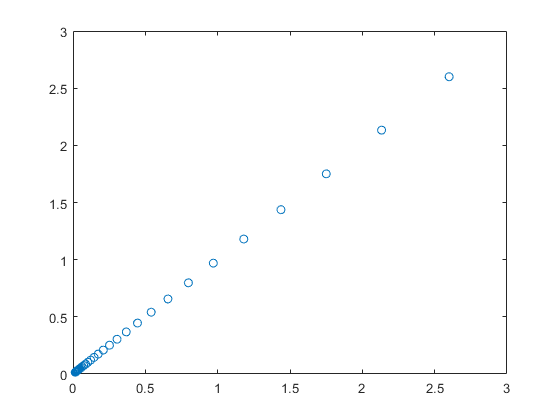

    temp = exp(linspace(log(1)*a, log(1.05)*a,n));
    %re-scale to be between 0 and 1
    temp_01 = temp/max(temp) - min(temp)/max(temp);
    %re-scale to be between your limits (i.e. 1 and 1.05)
    out = temp_01*(upper-lower) + lower;
    % plot(diff(out),diff(out),'o');
    plot(out,out,'o');

end

Apply linear segment with parabolic blend to generate trajectory 

total_traj_pos = [];
total_traj_vel = [];
total_traj_acc = [];

if (isTrajectory)
    endtime = 3;
    constime = (endtime/2)*0.5;  
    old_amp = (endtime/2)*out(1)/2/2 + constime*out(1)/2/2;
    for i = out
        ctr_freq = 1000;
        ctr_time = 1/ctr_freq;
        max_vel = i/ctr_freq;
%         max_vel = 1.1/4000;%i/ctr_freq;     
        endtime = 3;
        % 75 percent of motion is at constant velocity 
        constime = (endtime/2)*0.75;  
        % Position amplitude
        amp = (endtime/2 + constime)*max_vel*ctr_freq/2/2;
        amp_diff = amp + old_amp;

        [traj_pos, traj_vel, traj_acc] = lspb_core(-amp+amp_diff,amp+amp_diff,endtime,ctr_freq,max_vel);
        total_traj_pos = [total_traj_pos; traj_pos];
        total_traj_vel = [total_traj_vel; traj_vel];
        total_traj_acc = [total_traj_acc; traj_acc];
        old_amp = traj_pos(end);
    end
    csvwrite('trajectoryForTest/traj_pos.csv',total_traj_pos);
    csvwrite('trajectoryForTest/traj_vel.csv',total_traj_vel);
    csvwrite('trajectoryForTest/traj_acc.csv',total_traj_acc);
end

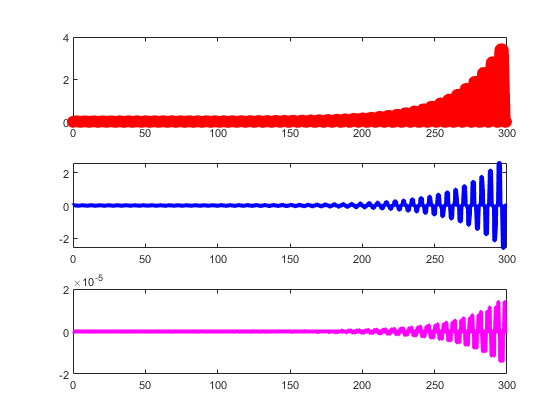

if (isPlot)
    figure;
    data_pos = load('trajectoryForTest/traj_pos.csv');
    data_vel = load('trajectoryForTest/traj_vel.csv');
    data_acc = load('trajectoryForTest/traj_acc.csv');

    t = 0:size(data_pos,1);
    t = t(1:end-1)/ctr_freq;
    subplot(3,1,1)
    plot(t,data_pos,'ro','linewidth',3);
    subplot(3,1,2)
    plot(t,data_vel*ctr_freq,'b','linewidth',3);
    subplot(3,1,3)
    plot(t,data_acc,'m','linewidth',3);
end